# **TO BUY OR NOT TO BUY?**

# ** USING A LONG SHORT-TERM MEMORY (LSTM)**

# ** NETWORK TO DRIVE BITCOIN PURCHASES **

# **PROJECT PROPOSAL**

# ** FOR UNIVERSITY OF VIRGINIA **

# **SYS 6014 DECISION ANALYSIS SPRING 2020 **

# **MARCH 25TH, 2020**

# **JAMIE QUINTANA**

### **TABLE OF CONTENTS**

- INTRODUCTION

- DECISION PROBLEM

- PREDICTIVE MODEL

- PRIOR BELIEFS

- DECISION MATRIX

- RESULTS* (partial results included)*

- CONCLUSION* (when finalized)*

- REFERENCES 

***Key Words:*** Bitcoins, binomial distribution, Bayesian analysis, decision making, classification, machine learning, Auto regression

***Reproducable Research:*** to create report, use Matlab 2019b or higher with all toolboxes, run live notebook 03_25_2020_SYS-6014_Project_Proposal_Final.mlx. Prerequisite files needed 2020_3_14_OPEN.csv, 2020_3_14_CLOSE.csv,  Y_Feb.mat, P_vector.mat, and Feb_Key.mat. 

### **Introduction**

     **U**se of the word “bitcoin” was virtually non-existent until ~2008.  The word first appeared in a white paper titled Bitcoin: A Peer-to-Peer Electronic Cash System credited to Satoshi Nakamotox on October 31st, 2008. The paper discussed a new approach to use a peer-to-peer system that would allow decentralized online cash exchanges without a third-party financial institution. Meaning, individuals could use this new type of crypto currency to send or receive bitcoins to other individuals directly. The proposed solution leveraged existing technologies including use of Digital signatures, as part of the solution, and suggested a new method of using network timestamps transactions, which culminate with a record that cannot be easily changed (Nakamoto, 2008).

The value of bitcoins have changed significantly since 2014. As an example, on Dec 1st, 2014 the bitcoin to dollar equivalency was one bitcoin was worth $370 U.S Dollars. Today, the current exchange rate of one bitcoin equals $9,922; so, that same $370 will buy you only a fraction of a bitcoin. Since the value of bitcoins changes could be based on many factors, the type of problem being addressed in this paper is focused on tactical purchases. That is, buying bitcoins to trade or use on the same day or at most the next day. To cite an example, if a person buys $500 of bitcoins on Feb 19th 2020, and then wants to purchase something the next day, that original $500 in bitcoins is worth only $471 dollars on Feb 20th, 2020; hence, a ~$29 loss in value. For this reason, this project topic is concerned with crypto currencies and when might be the best or optimal time to buy Bitcoins. That is, ideally, a decision maker would endeavor to buy currency on a day the price will likely go up vice down. Unlike stocks, crypto currency prices change based on various factors and is tracked every day. The focus here is to take the historical data (which is readily available) draw the line say at the end of Dec 31, 2019, and calculate probabilities for each day – Monday-Sunday to determine if one or more days are preferred to buy than another (calculate utility/loss functions for each, which will drive the decision to buy (or not). Basically – the price can go up or down (i.e. binary) from one day to the next **p =.5**; however, the actual probabilities may be (and most likely are) different depending on the overall data set (summed) or calculated for each day, each month, or determined by some prediction model. 

To establish a baseline, the binomial distribution can be used to examine the probabilities of events occurring based on some properties of the random variable. In this case, the random variable is the state of the bitcoin price going up or down. Here, the success of the trial occurs when the price goes up (i.e. the desired outcome). The assumptions here are each trial is independent and not influenced by the previous result. The probability density function of the binomial distribution is as follows: 

## 
$$$$ P(A) = \sum P(\{ (d_1,...,d_N) \})  = {{N}\choose{k}  }p^kq^{N-k}$$)
$$


Where ***d*** if the number of days and ***N*** is the number of trials. ***P*** is the probability of success (in this case p = .5) and ***k*** is the desired number of successes. As an example, considering the next 30 days, Bitcoin prices have a 50-50 chance of going up or down. So, if we to determine the probability of randomly guessing the price will go up (i.e. be a success) for 15 of those 30 days, the probability equals:

1 - binocdf(15,30,0.5)

ans = 0.4278

Which means, at ~43%, the odds are fairly low that a person using no other tools would have a low success rate at making a decision to buy Bitcoins and getting the desired results. If we assume we can build a prediction model that can increase the probability of success from .5 to say, .66, then the following chart plots out the Cumulative Density Function over those probabilities:

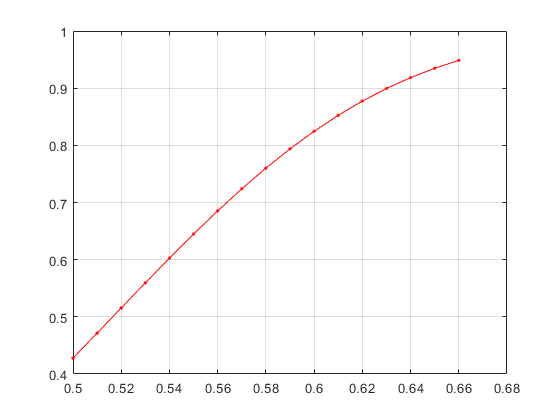

chance = 0.5:0.01:0.66;
y = 1 - binocdf(15,30,chance);
plot(chance,y, 'r.-')
grid on

As shown in the plot, the probability of getting 15 predictions correct increases significantly to 90% when the probabilty of success is increased to .63. So, the goal of this project is to increase the rate of probability to determine the next "success" to some probability > .5.  Even though, this seems promising as an example,  here the success rate is still 15/30 = 50% accuracy, which is actually not very good taken as a whole. 

### Decision Problem

**        A**s mentioned in the previous section, the decision maker has a menu of options at his or her disposal. The decision-maker's ***action set*** $A$ is a complete itemization of all the options available to the decision-maker, from which the decision-maker selects a unique choice. In this project, we define ${\mathit{\mathbf{a}}}_{\mathit{\mathbf{d}}}$ to be a binary control variable that takes a value of **1** if a decision to buy bitcoins on date **d**, and **0 **otherwise. Let random variable $X$** = **($\left.x_{d,\;} x_{d-1,\ldotp \ldotp \ldotp \ldotp \ldotp \;} x_1 \right)$denote the vector of potential probabilities, which the decision maker will encounter and let **a = **($\left.a_{d,\;} a_{d-1,\ldotp \ldotp \ldotp \ldotp \ldotp \;} a_1 \right)$ denote the vector of all decisions taken on givens days which consume a given budget ***B***. For this project, the max budget ***B***  is set at **$5,000**. Then $a\cdot x=\sum a_d x_d$  is the realized number of successful purchases (where bitcoin price went up as predicted) per given day.   The goal to maximize in expectation the total number of successful purchase days, which can be expressed as (Small, et al, 2010) :

## $\underset{a}{\textrm{MAX}}$ ***E*** [$a\cdot x$] subject to budget constraint $\sum a_d$ $\le B$

This project creates a scenario where the decision maker has to make ten purchases each **@ $500** of bitcoins during the month of February using the decision tools in this project. As a comparison, the results of the maximized decisions using the model's data will be compared against a newly generated probability distribution of potential outcomes for the month of February to compare the performance (i.e. the value) of the model*. *Below is a full list of actions which the decision maker will make... other possible actions can/may be added as the course progresses. 

##   **Actions**  - ***No.  Description ***

------------------------> 1  Do not buy bitcoins 

------------------------> 2  Buy bitcoins without using model data 

------------------------> 3  Buy bitcoins on Mondays 

------------------------> 4  Buy bitcoins on Tuesdays 

------------------------> 5  Buy bitcoins on Wednesdays 

------------------------> 6  Buy bitcoins on Thursdays 

------------------------> 7  Buy bitcoins on Fridays 

------------------------> 8  Buy bitcoins on Saturdays 

------------------------> 9  Buy bitcoins on Sundays 

------------------------> 10  Buy bitcoins based on price prediction forecast (next day prediction: up or down)

**Note* the context for "next day" hence forward in this paper is the day immediatly following the model's last known Open and Close values. Meaning, the ****predicted day**** is the current day's opening price for which the closing price is still unknown.  **

The success criteria for the project is simple. The goal of the project is to use the model's prediction capabilites to either break even (no loss) or make a positive gain. The project will be viewed as a failure if the end results culminate in a loss**.**

### **Prediction Model**

**        S**pecifically tied to action no. 10 as described above, this action requires creating a prediction model using linear regression, auto regression, or some other deep learning algorithim over the short term. For example, auto regression is a specific time series model that examines data points from previous time steps (in this case a previous set of days) as inputs to forecast or predict the next day value. Like auto regression, a long short-term memory (LSTM) network can be used to forecast the time series data, so this project will notionally use that technique to forecast future values. The core model will use historical time series data exclusively to predict the next day's price value. The objective here is to create a model "baseline" from which subsequent days can be "added" to the last day to predict the next day's outcome. The diagram below provides a visual description of this project's model baseline step:

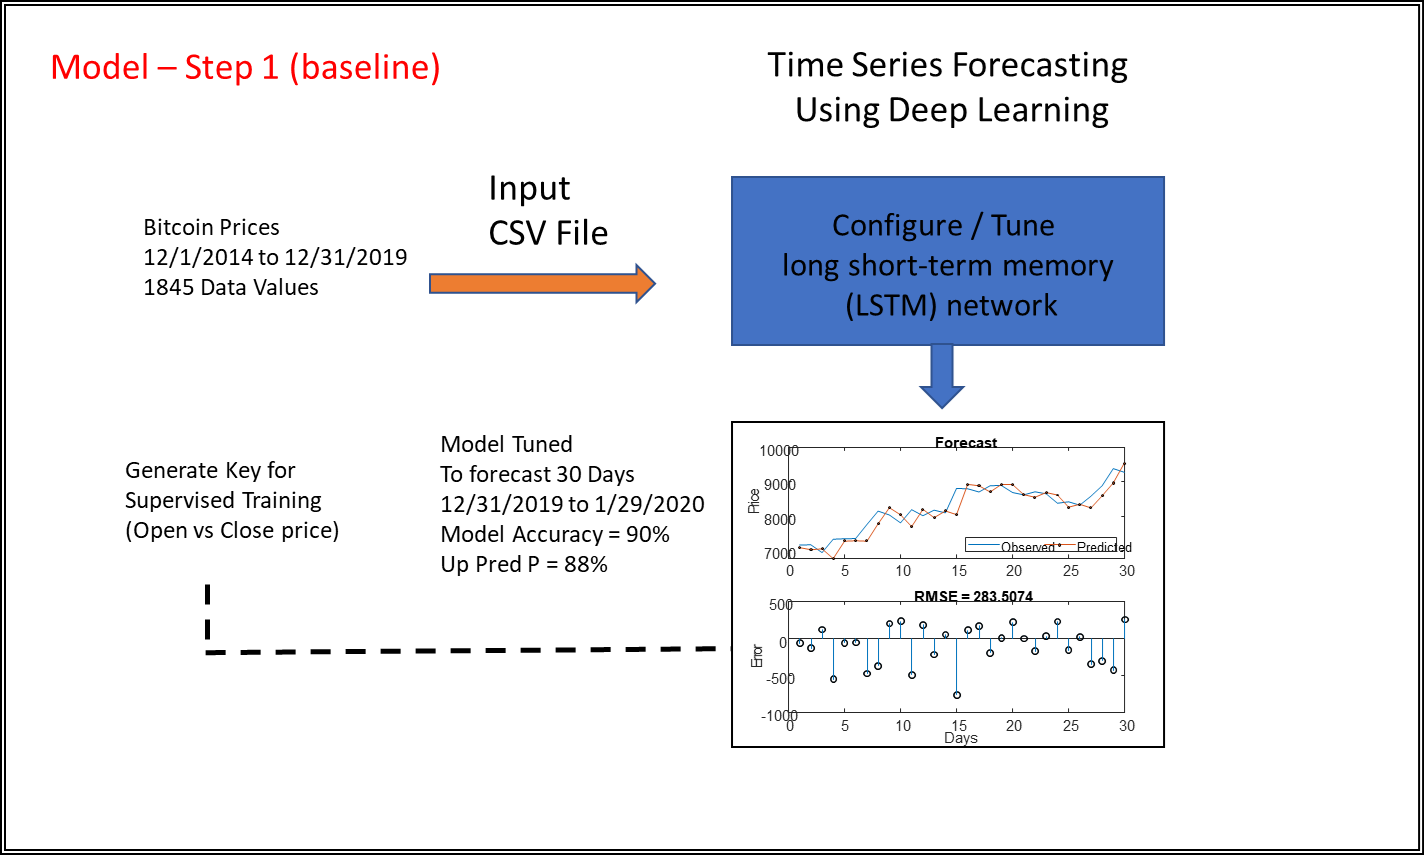

The models accuracy will be based on actual states of the prices going up or down versus predicted outcomes. In this case, we will examine the random variable  $Y\;$containing $y$ samples generated by the model. The goal will be to minimize the error components **E** based on the following expression: 

## 
$$Y_{\left(T+1\right)} =\beta_0 +\;\beta_1 *y_{\left(t-1\right)} +\;\beta_2 *y_{\left(t-2\right)} \ldotp \ldotp \ldotp \ldotp \ldotp +\;\beta_{30} *y_{\left(t-30\right)} +\varepsilon_T$$
 

Here, **T** = total number of days (i.e. 30), **t **= time steps (or specific day in the time series), **Y** is the random variable, **e** are the error components, and **B** are the coeffiecents.

clear all;
close all;
rng(345); %for reproducability
days = 30; %days to forecast  - set to 30 for baseline - set to 5 for predictor window 
Fdays = 0; %sliding window - days to skip after 12/31/2019, which counts as day 1 - set to 0 to baseline model - no skip days
%Setting days = 33  and Fdays = 0 to predict 2/1/2020 (up or down) with forecast window of 12/31/2019 to 1/31/2020 
%Setting days = 30 and Fdays (skip days) = 3 predicts 2/1/2020 also

The code above clears all charts, plots, and variables prior to executing. The variable **days** are set for the forecast windows and **Fdays** are days to skip - allowing the sliding window to move along dates without adjusting any other model parameters. Below chart shows how the prediction sequence will work:

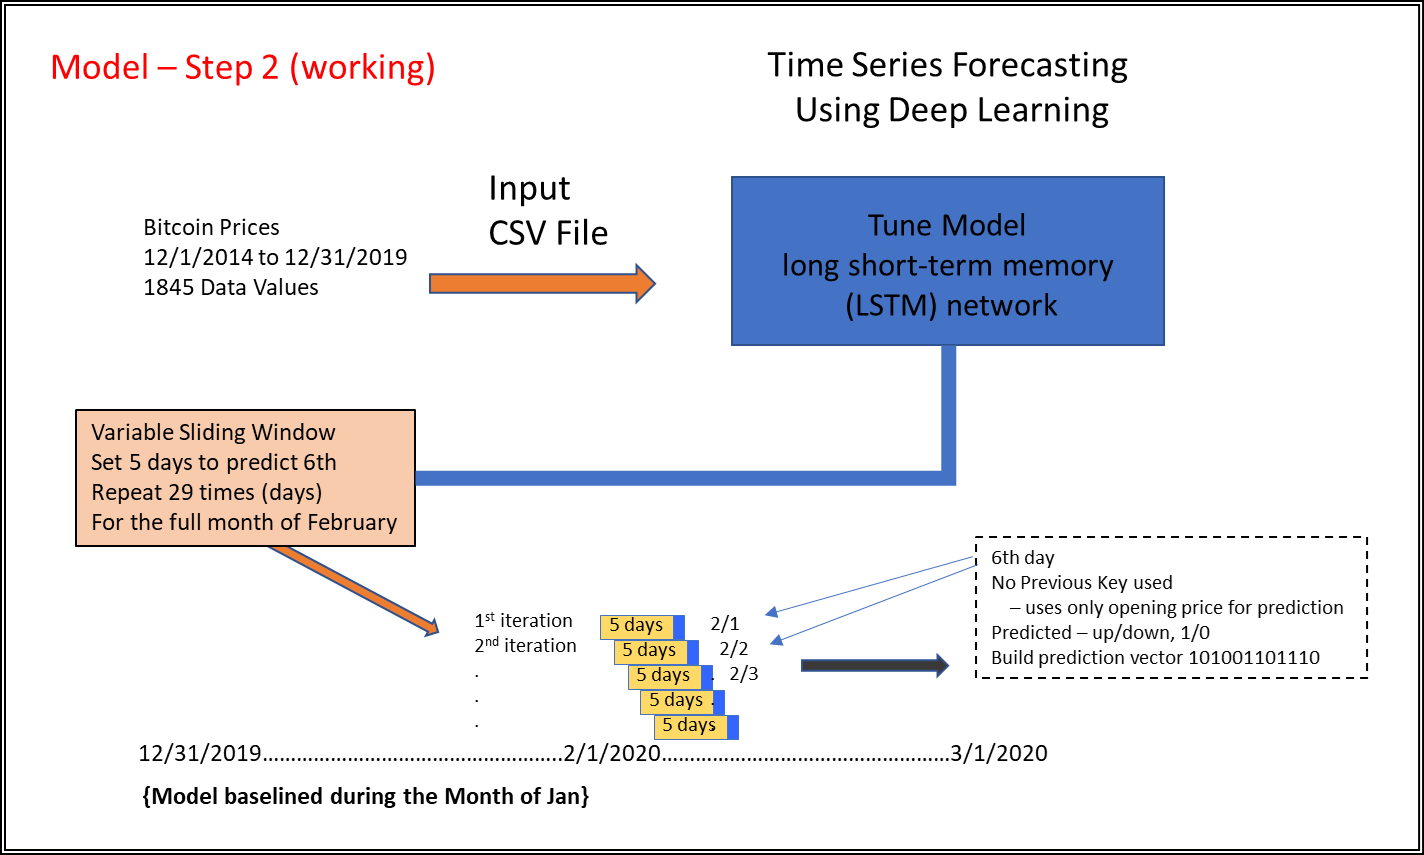

input = csvread('2020_3_14_OPEN_Key.csv');
data = input;
data = data';
input2 = csvread('2020_3_14_CLOSE_Key.csv');
data2 = input2;
data2 = data2';

The code above loads the opening and closing prices which are used to autogenerate a Key, which is only used to determine the model's performance after tuning the model to minimize the error components during the regression process. 

num = length(input);
fprintf('Last possible day to predict')

Last possible day to predict

DateString = datestr(737790+(num-1845))

DateString = '14-Mar-2020'

The code above prints in the command window the "last"possible date model can predict a value based on the number of values in the Open.csv data vector. 

Mkey = data2 - data;
Mkey( Mkey >= 0 ) = 1;
Mkey( Mkey < 0 ) = 0;
Mkey = Mkey';
KEY = Mkey(1845+Fdays:1844+Fdays+days);

The code above calculates the model's Key as a subset of **Fdays** and **days** - again, no key is generated for the "next day". A "1" is generated when the closing price is higher than the opening price and "0" otherwise. 

**Mkey** = **J**, where **J** = $C_i$ - $O_i$, where **C** is the closing price at day ***i***, and **O** is the opening price at **i**, $\forall$ **i**'s, where **I** is the number of **days** in the prediction window. 

Once the model parameters have been configured in a way that minimizes the residual errors in the prediction price vector, and binary sequence will be generated to forecast whether next day's price will go up or down when subtracting observed - predicted or predicted - observed. The resulting binary vector (i.e. 01010011100011), will be compared against a key to determine actual model performance; once the highest value of performance is obtained, the model parameters will be locked down, and only subsequent days, one day at a time, will be added to determine the next day's decision (i.e. to buy or not). 

numTimeStepsTrain = 1844;%1845 = 12/31/2019
WIN = (numTimeStepsTrain+1+days);
dataTrain = data(1:numTimeStepsTrain+1); %train model up to 12/31/2019 
dataTest = data(numTimeStepsTrain+1+Fdays:WIN+Fdays);
mu = mean(dataTrain);
sig = std(dataTrain);
dataTrainStandardized = (dataTrain - mu) / sig;
XTrain = dataTrainStandardized(1:end-1);
YTrain = dataTrainStandardized(2:end);
numFeatures = 1;
numResponses = 1;

The code above sets the initial perameters of the model - **numTimeStepsTrain** is set to 1844 and adds one as a predictor read-ahead, which corresponds to 12/31/19 (1845). This means the model will use all data values up to 1845 in the Open.csv data vector to train the prediction engine. **Note* all predicted values after 12/31/19 use the model's data to predict values - these settings are never changed**.  

numHiddenUnits = 17; %17 = %94.33
layers = [ ...
    sequenceInputLayer(numFeatures)
    lstmLayer(numHiddenUnits)
    fullyConnectedLayer(numResponses)
    regressionLayer];
    options = trainingOptions('sgdm',... %'sgdm' 'adam'
    'MiniBatchSize',1,...
    'MaxEpochs',175, ...
   'GradientThreshold',1, ...
    'InitialLearnRate',0.08, ...
    'LearnRateSchedule','piecewise', ...
    'LearnRateDropPeriod',125, ...
    'LearnRateDropFactor',0.3, ...
    'Verbose',0, ...
   'Plots','no');
net = trainNetwork(XTrain,YTrain,layers,options);


The code above creates an LSTM regression network and specifes the LSTM layer to have 17 hidden units. **Note* numHiddenUnits, trainingOptions, MiniBatchSize, MaxEpochs, GradientThreshold, InitialLearnRate, InitialLearnRate, LearnRateSchedule, LearnRateDropPeriod, **and** LearnRateDropFacto**r will all be adjusted to maximize the model's performance and not changed when using the model to predict the next day's value. 

dataTestStandardized = (dataTest - mu) / sig;
XTest = dataTestStandardized(1:end-1);
net = predictAndUpdateState(net,XTrain);
[net,YPred] = predictAndUpdateState(net,YTrain(end));

numTimeStepsTest = numel(XTest);
for i = 2:numTimeStepsTest
    [net,YPred(:,i)] = predictAndUpdateState(net,YPred(:,i-1),'ExecutionEnvironment','cpu');
end
YPred = sig*YPred + mu;
YTest = dataTest(2:end);
rmse = sqrt(mean((YPred-YTest).^2));

The code above makes prediction based on the training data `XTrain ``as discussed earlier` using the last time step of the training response `YTrain``(end) and then l`oops over the remaining predictions.

net = resetState(net);
net = predictAndUpdateState(net,XTrain);
YPred = [];
numTimeStepsTest = numel(XTest);
for i = 1:numTimeStepsTest
    [net,YPred(:,i)] = predictAndUpdateState(net,XTest(:,i),'ExecutionEnvironment','cpu');
end
YPred = sig*YPred + mu;
rmse = sqrt(mean((YPred-YTest).^2));

The code above is used when the actual values of time steps between predictions is known (as in the case of this project) and updates the network state using **predictAndUpdateState** with the observed values instead of the predicted values.

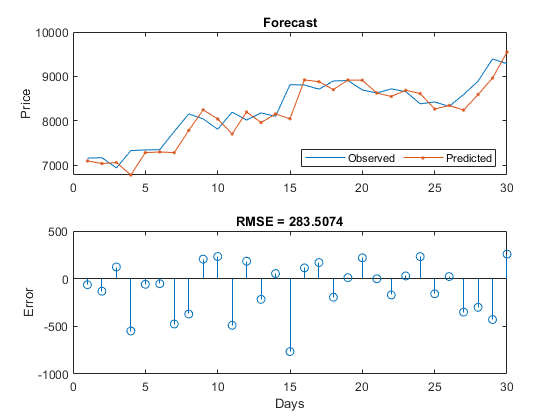

figure
subplot(2,1,1)
plot(YTest)
hold on
plot(YPred,'.-')
hold off
legend(["Observed" "Predicted"])
legend({'Observed','Predicted'},'Location','southeast','NumColumns',2)
ylabel("Price")
title("Forecast")
subplot(2,1,2)
stem(YPred - YTest)
xlabel("Days")
ylabel("Error")
title("RMSE = " + rmse)

The code above generates a plot of the predicted versus observed (i.e. true) values .

DIF = YTest-YPred;
DIF( DIF >= 0 ) = 1;
DIF( DIF < 0 ) = 0;
DIF = DIF';
Percent_of_similar_bits = sum(KEY==DIF)/days;
fprintf('Percentage Correct  : %f%%\n', 100*Percent_of_similar_bits)

Percentage Correct  : 90.000000%


tkey = (KEY==DIF);
Fkey = tkey+KEY;
UP_Prob = sum(Fkey==2)/sum(DIF==1)

UP_Prob = 0.8824

The above code calculates the difference bewtween the predicted model values against the real, observed values to determine the model's operating performance (in order to lock down the parameters discussed above). Where we define **DIF** = **D**, where **D** = $X_i$ - $Y_i$,  where **X** is the Opening price at day ***i***, and **Y** is the predicted price at **i**, $\forall$ **i**'s, where **I** is the number of **days** in the prediction window. **UP_Prob **simply provides a ratio of how many times the model predicted an up value against the number of up values observed. One of the goals of this project is to maximize this value to the extent possible.

fprintf('Current day prediction - Up (1) or Down(0)?')

Current day prediction - Up (1) or Down(0)?

DateString = datestr(737790+days+Fdays)

DateString = '30-Jan-2020'

The above code simply shows the current day prediction - either up or down based on the values calculated below:

CDP1 = YPred(end)-mean (YTest);% 5 day windows best
CDP1( CDP1 >= 0 ) = 1;
CDP1( CDP1 < 0 ) = 0;
CDP2 = (YTest(end)-(mean (YPred)*1.05))*-1;
CDP2( CDP2 >= 0 ) = 1;
CDP2( CDP2 < 0 ) = 0;
P_Key = CDP1+CDP2;
if P_Key ==2
    P_Key =1
else
    P_Key =0
end

P_Key = 0

The code above is critical to the model in order to predict the next day's value (up or down).  

Let** CDP1** = **C1**, where **C1** = $y_5$ - $\frac{\sum_i^5 x_i }{5}$ -   where **y** is the opening price at day 5, and **x** is the predicted price at day **i**, $\forall$ **i**'s.  Here, if resulting value is equal to or greater than one (i.e. positive), then **CDP1=1**. Otherwise, set to 0.

Let** CDP2** = **C2**, where **C2** = $x_5$ - $\frac{\sum_i^5 y_i }{5}$ -   where **x** is the predicted price at day 5, and **y** is the observed price at day **i**, $\forall$ **i**'s.  Multiplying by 1.05 and -1, which flips the sign and scales up the mean by 5%. Here, if resulting value is equal to or greater than one (i.e. positive), then **P_Key=1**. Otherwise, set to 0.

When both **CDP1** and **CDP2** = **1**, the probability increases that next day's price will be up (i.e. set to 1). All other combinations results in 0 (i.e. price should go down).

Both **Type I** and **Type II** errors in the model's prediction vector will be captured and recorded in the results section of this report. A type I error occurs when the model predicts day will be "up", but day turns out to be down (as an example). It's akin to a false positive. A type II error occurs when the model predicts day will be "down", but day turns out to be up (as an example). This is a akin to a false negative.  

For this project, the state space or sample space is defined *as *Χ. The full set of direct data will be used, but not altered from its original state. Instead, the sample space for each action will be derived (i.e. calculated) from the full set of data as described in the next section. Full data set contains 6 columns of numerical 1898 data points (i.e. from 12/1/2014 to 3/14/2020) with column titles - Open, High, Low, Close, Volume BTC, and Volume USD. This can be considered a data generating process, which takes the form of a statistical model describing the statistical properties of random variables  ${}x_1$,${}x_2$,…,${}x_n$∈ X. So for the observed random variable **X** ${}x_i$,~ 263 data points will be parsed (i.e. filtered) from the entire data set for each day of the week. Then, each group of 263 ~ data points will be divided into two groups: first group summing all times the bitcoin price when up, and second for all times the prices went down. Then their associated  $L\left(\theta ,a\right)$'s will be calculated for each day. A quick look at the entire data set reveals that neither price going up or down is a rare occurrence (i.e. 2% over the lifetime of bitcoins). Additionally, since 8/12/2018 the price of bitcoins have not once remained the same from open to close, so for the project, the probability that the price remains the same is left out of the decision model. To account for any future occurrences, the model will treat a no gain or loss day as a success - which makes intuitive sense, because no money was actually lost. 

For this project, the complete *parameter space *$\Theta$ containing all the possible states will be contained within $\Theta =\left\lbrack 0,1\right)$, with set of all possible values of θ and ${}{\sigma }^2$: $\Theta =R\times \left\lbrack 0,\infty \right)$.Although, most of the observed θ's with be roughly in the ~.5 range with the goal of the project that predictive model will obtain $L\left(\theta ,a\right)$'s with $\theta^{\prime } s\;$above the .5 value nearing .6 or .7 if achievable. 

The source of data used in this project will be downloaded from here: URL for full data source (updated hourly, daily): http://www.cryptodatadownload.com/data/coinbase/

The code, from which this project's model is based, was obtained from here: [https://www.mathworks.com/help/deeplearning/examples/time-series-forecasting-using-deep-learning.html](https://www.mathworks.com/help/deeplearning/examples/time-series-forecasting-using-deep-learning.html)

### **Prior Beliefs**

**        T**his section discusses the decision-maker's ***prior beliefs ***$\pi \left(\theta \right)$*. *These beliefs describe the information or beliefs the decision-maker has about the values of the unobserved parameters before collecting data. These beliefs can generally be represented as a probability distribution over the parameter space $\Theta$. I think most people (i.e. decision makers) believe there is no real, consistent, reliable way to determine when is the best time to make a purchase - almost regardless of what it is (assuming whatever stock or asset being purchased is optional and not mandatory). Point in case is the plot below of bitcoin prices from the very start until Dec 31st, 2019. Unlike the random prediction varaible $Y$, the actual probabilities for the complete set of **X **data can be calculated. 

As seen in the plot below, the price changes from one day to the next seem erratic or stochastic vice deterministic or even linear.  Over the short term, the patterns in the data may appear to follow trends either upward or downward.

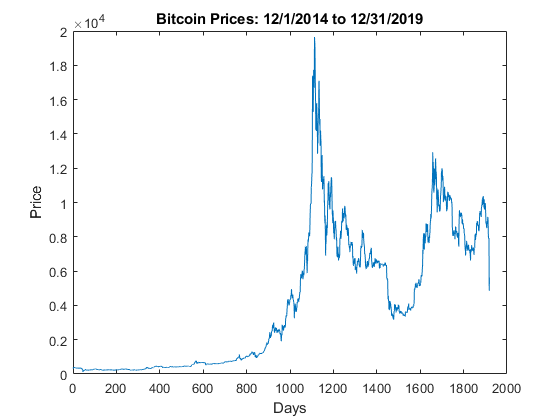

figure
plot(data)
xlabel("Days")
ylabel("Price")
title("Bitcoin Prices: 12/1/2014 to 12/31/2019")

So, in the case of this project, any prior belief that there exists some method or previous way to determine if price will go up or down is off the table. Meaning, project will assume the probability is 50/50 **(p = .5)** one way or another and no external factors or variables outside the data set will be used or referenced. So without trying to quantify the amount of price increases or decreases, the simple answer to the question of "will bit coins go up or down the next day" is binary. That is, yes or no. 

This project will use Bayes Rule, also known as Bayesian Inference (Hoff, 2009), as a way to determine or understand how new information may impact or change one’s previous view about some probability distribution or likelihood of events occurring. The Bayesian method helps by providing the following:

"• parameter estimates with good statistical properties;

 • parsimonious descriptions of observed data;

 • predictions for missing data and forecasts of future data;

 • a computational framework for model estimation, selection and validation" (Hoff, pg.1, 2009).

The following expression describes Bayes Rule, which details the posterior distribution:

###  
$$p\left(\theta \left|y\right.\right)=\frac{p\left(y\left|\theta \right.\right)p\left(\theta \right)}{\int_{\Theta } p\left(y\left|\theta^ˆ \right.\right)p\left(\theta^ˆ \right)d\theta^ˆ }$$


Where $p\left(\theta \right)$ and $p\left(y\left|\theta \right.\right)$represent a the person’s current beliefs and $p\left(\theta^ˆ \right)$ and $p\left(y\left|\theta^ˆ \right.\right)$ represent new information which could alter a person's beliefs (aka posterior beliefs). The posterior probability is the resulting probability that an event will occur once additional information has been gathered, learned, or predicted. Depending on the new information, it could change prior belief by either supporting a claim or providing evidence to the contrary. The prior probability or beliefs in this project will be close to 50/50 or p=.5 in which is the probability of the bitcoin price going up or down will occur. 

The relevant ***payoffs*** that could result from the action. Payoffs will be a function of the selected action **a**, where we le ***u( a , x)*** represent the payoff based on action **a**, and the realized value (or state) of our random variable  ***x***** = **($\left.x_{d,\;} x_{d-1,\ldotp \ldotp \ldotp \ldotp \ldotp \;} x_1 \right)$.  The expression below represents the expected payoff in terms of **U*****( a , ***$\theta$***) ***as a function o***f ***$\theta$ (Small, 2020):

##  $U\left(a,\theta \right)$*** = ***$E\;\left\lbrack u\left(a,\chi \right)\left|\theta \right.\right\rbrack =\;$$\int_{\chi } p\left(x\right)u\left(a,x\right)\textrm{dx}$

The goal of the model is to optimize making a decsion to buy bitcoins on a particular day ***where the model has determined the price should go up***; hence, the decision maker made a good choice to buy where either money is not lost or at worse remains the same without a loss. The performance of the model will be gauged against the probabiliy of making or losing money during the month of February, where the mean gain/loss for the month is -$13.5 (i.e. value of purchase at $500 vs value at closing) .  So, this model can be considered a success in the eyes of the author if the performance of the model produces any positive gain at the end after purchasing 10 days (i.e. the first 10 model predictions) of bitcoins at $500 per purchase. For sake of consistency, the purchase of bitcoins will all occur at the opening price (i.e. midnight) to keep the math consistent and repeatable.  The code below provides a bootstrap method of creating a probability distribution based soley on the month of February (i.e. repeatedly taking a sample from the gains and losses occured during the month 100,000 times).

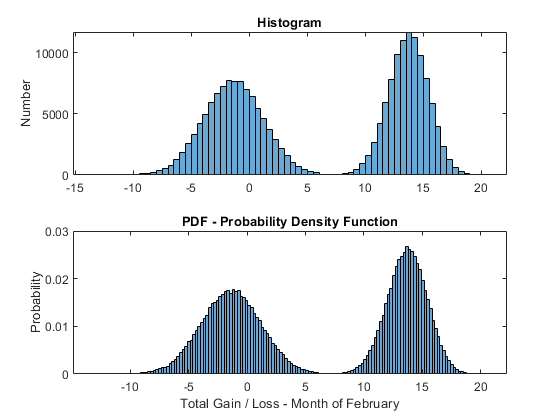

load('Y_Feb.mat');
stats = bootstrp(100000,@(x)[mean(x) std(x)],y);
figure
subplot(2,1,1)
histogram(stats)
ylabel("Number")
title("Histogram")

subplot(2,1,2)
edges = 150;
h = histogram(stats,edges, 'Normalization','probability');
title("PDF - Probability Density Function")
xlabel('Total Gain / Loss - Month of February')
ylabel('Probability');

S = [];
for t = 1:100000;
nA = numel(y);
numsamples = 10;
samples = y(randi(nA,[numsamples,1]));
St = sum(samples);
S(t)=St;
end;

The code above simulates collecting 10 of the 29 days in February's gains/losses 100,000 times to generate a new probability density function, where the probability of obtaining a certain value can be calculated and compared against the value the model produces. 

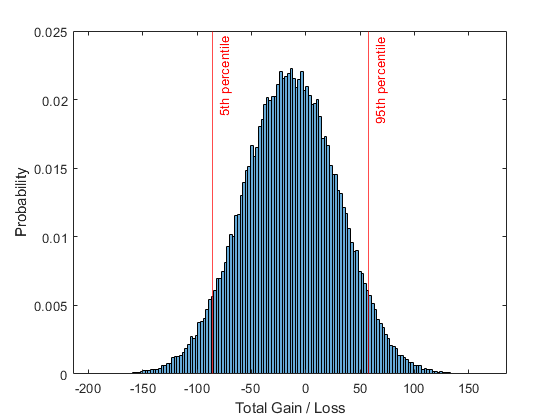

figure
h = histogram(S,edges, 'Normalization','probability');
xlabel('Total Gain / Loss')
ylabel('Probability');
hold on
pt = prctile(S,5);%cuttoff of the distribution that defines 5% of the data on the left
xline(pt, 'r-', '5th percentile');
pt = prctile(S,95);%cuttoff of the distribution that defines 95% of the data on the right
xline(pt, 'r-', '95th percentile');

mean(S) % Mean gain/loss for the month of February

ans = -13.5438

### **Decision Matrix**

**        F**or the proposed model, a decision matrix will be generated to help drive the optimal decision. Different values associated with each action selection could be based on three different risk profiles (i.e. *Risk Neutral, Risk Averse, and Risk Seeking*). Table below is notionally Risk Neutral. Additional tables can be generated based on actual amount of investment i.e. values adjusted non linearly as quantity of the bitcoin purchase increases - perhaps, $100, $1000, and $10000 options. The below chart is one of the project deliverables. 

Actions = ["Do not buy bitcoins", "Buy bitcoins without model data","Buy bitcoins on Mondays","Buy bitcoins on Tuesdays","Buy bitcoins on Wednesdays","Buy bitcoins on Thursdays","Buy bitcoins on Fridays","Buy bitcoins on Saturdays","Buy bitcoins on Sundays","Buy bitcoins using predictive models"];
PriceUp = [.5,.5,.43,.47,.53,.49,.56,.51,.42,.88];
PriceDown = [.5,.5,.57,.53,.47,.51,.44,.49,.58,.12];
ValueSuccess = [3,10,10,10,10,10,10,10,10,10];
ValueFailure = [0,-10,-10,-10,-10,-10,-10,-10,-10,-10];
Payoff = [1.5,0,-1.4,-.6,.6,-.2,1.2,.2,-1.6,2];
Actions = Actions';PriceUp = PriceUp';PriceDown = PriceDown'; ValueSuccess = ValueSuccess';ValueFailure = ValueFailure';Payoff = Payoff';
table1 = table(Actions,PriceUp,PriceDown,ValueSuccess, ValueFailure, Payoff);
table1

table1 = 10×6 table
                   Actions                    PriceUp    PriceDown    ValueSuccess    ValueFailure    Payoff
    ______________________________________    _______    _________    ____________    ____________    ______

    "Do not buy bitcoins"                       0.5         0.5             3               0           1.5 
    "Buy bitcoins without model data"           0.5         0.5            10             -10             0 
    "Buy bitcoins on Mondays"                  0.43        0.57            10             -10          -1.4 
    "Buy bitcoins on Tuesdays"                 0.47        0.53            10             -10          -0.6 
    "Buy bitcoins on Wednesdays"               0.53        0.47            10             -10           0.6 
    "Buy bit

**Note:** the $\pi \left(\theta \right)$ for actions 1 and 2 is assumed. and the ${\left(\theta \right)}^{\prime } s\;$for actions 3 through 10 are synthetic or simulated (placeholders for the real values to be calculated). Also, instead of a negative perpective of using a loss function, project will use a positive payoff perspective - seeking higher values being the best choice to drive the decision.   

### Results 

The code and results shown here show how the baseline model's accuracy was determined in the prediction model section.

figure
subplot(2,1,1)
plot(YTest)
hold on
plot(YPred,'.-')
hold off
legend(["Observed" "Predicted"])
legend({'Observed','Predicted'},'Location','southeast','NumColumns',2)
ylabel("Price")
title("Forecast")
subplot(2,1,2)
stem(YPred - YTest)
xlabel("Days")
ylabel("Error")
title("RMSE = " + rmse)

load('P_vector.mat');
load('Feb_Key.mat');
DIF = YTest-YPred;
DIF( DIF >= 0 ) = 1;
DIF( DIF < 0 ) = 0;
DIF = DIF';
Percent_of_similar_bits = sum(KEY==DIF)/days;
fprintf('Percentage Correct  : %f%%\n', 100*Percent_of_similar_bits)

Percentage Correct  : 90.000000%


tkey = (KEY==DIF);
Fkey = tkey+KEY;
UP_Prob = sum(Fkey==2)/sum(DIF==1)

UP_Prob = 0.8824

Of note here is the fact that the probability of the model getting the right answer when it determines the price should go up is more critical than the overall model performance at 90%. This makes sense since the goal of this model is mainly to predict "ups" vice downs, but both are obviously important.   Here, over the first 30 days past 12/31/19, this model has done an good job on predicting when the price will go up at **~.88** probability. 

The section of code below was used to calcuate the model probability in the decision matrix. It uses the baseline model, sets forecast **days** = **5** (doesn't change) and **FDays** are incremented by one after each iteration until the full month of January is complete. Only two days in January are shown here to conserve space, but when comeplete, the prediction vector (i.e. 0101010010010101010101010111101) will be compared agasin the key vector to determine model accuracy.  In total, 27 days (the 5th through the 31th) are predicted in January to determine the model's baseline probability for the decision model - note, the Up probability will be used versus the model's overall  accuracy, since that is the objective of this project. 

days = 5; %days to forecast - set to 5 for predictor window 
Fdays = 0; %start at 0, then increment by 1 - execute code, repeat. 
KEY = Mkey(1845+Fdays:1844+Fdays+days);
numTimeStepsTrain = 1844;%1845 = 12/31/2019
WIN = (numTimeStepsTrain+1+days);
dataTrain = data(1:numTimeStepsTrain+1); %train model up to 12/31/2019 
dataTest = data(numTimeStepsTrain+1+Fdays:WIN+Fdays);
mu = mean(dataTrain);
sig = std(dataTrain);
dataTrainStandardized = (dataTrain - mu) / sig;
XTrain = dataTrainStandardized(1:end-1);
YTrain = dataTrainStandardized(2:end);
numFeatures = 1;
numResponses = 1;
numHiddenUnits = 17; %17 = %94.33 

layers = [ ...
    sequenceInputLayer(numFeatures)
    lstmLayer(numHiddenUnits)
    fullyConnectedLayer(numResponses)
    regressionLayer];
    options = trainingOptions('sgdm',... %'sgdm' 'adam'
    'MiniBatchSize',1,...
    'MaxEpochs',175, ...
   'GradientThreshold',1, ...
    'InitialLearnRate',0.08, ...
    'LearnRateSchedule','piecewise', ...
    'LearnRateDropPeriod',125, ...
    'LearnRateDropFactor',0.3, ...
    'Verbose',0, ...
   'Plots','no');
net = trainNetwork(XTrain,YTrain,layers,options);
dataTestStandardized = (dataTest - mu) / sig;
XTest = dataTestStandardized(1:end-1);
net = predictAndUpdateState(net,XTrain);
[net,YPred] = predictAndUpdateState(net,YTrain(end));

numTimeStepsTest = numel(XTest);
for i = 2:numTimeStepsTest
    [net,YPred(:,i)] = predictAndUpdateState(net,YPred(:,i-1),'ExecutionEnvironment','cpu');
end
YPred = sig*YPred + mu;
YTest = dataTest(2:end);
rmse = sqrt(mean((YPred-YTest).^2));

net = resetState(net);
net = predictAndUpdateState(net,XTrain);
YPred = [];
numTimeStepsTest = numel(XTest);
for i = 1:numTimeStepsTest
    [net,YPred(:,i)] = predictAndUpdateState(net,XTest(:,i),'ExecutionEnvironment','cpu');
end
YPred = sig*YPred + mu;
rmse = sqrt(mean((YPred-YTest).^2));
DIF = YTest-YPred;
DIF( DIF >= 0 ) = 1;
DIF( DIF < 0 ) = 0;
DIF = DIF';
fprintf('Current day prediction - Up (1) or Down(0)?')

Current day prediction - Up (1) or Down(0)?

DateString = datestr(737790+days+Fdays)

DateString = '05-Jan-2020'


CDP1 = YPred(end)-mean (YTest);% 5 day windows best
CDP1( CDP1 >= 0 ) = 1;
CDP1( CDP1 < 0 ) = 0;
CDP2 = (YTest(end)-(mean (YPred)*1.05))*-1;
CDP2( CDP2 >= 0 ) = 1;
CDP2( CDP2 < 0 ) = 0;
P_Key = CDP1+CDP2;
if P_Key ==2
    P_Key =1
else
    P_Key =0
end

P_Key = 1

This next section repeats the process, but skips to predicting the last day in Jan.

days = 5; %days to forecast - set to 5 for predictor window 
Fdays = 26; %start at 0, then increment by 1 - execute code, repeat. 
KEY = Mkey(1845+Fdays:1844+Fdays+days);
numTimeStepsTrain = 1844;%1845 = 12/31/2019
WIN = (numTimeStepsTrain+1+days);
dataTrain = data(1:numTimeStepsTrain+1); %train model up to 12/31/2019 
dataTest = data(numTimeStepsTrain+1+Fdays:WIN+Fdays);
mu = mean(dataTrain);
sig = std(dataTrain);
dataTrainStandardized = (dataTrain - mu) / sig;
XTrain = dataTrainStandardized(1:end-1);
YTrain = dataTrainStandardized(2:end);
numFeatures = 1;
numResponses = 1;
numHiddenUnits = 17; %17 = %94.33 

layers = [ ...
    sequenceInputLayer(numFeatures)
    lstmLayer(numHiddenUnits)
    fullyConnectedLayer(numResponses)
    regressionLayer];
    options = trainingOptions('sgdm',... %'sgdm' 'adam'
    'MiniBatchSize',1,...
    'MaxEpochs',175, ...
   'GradientThreshold',1, ...
    'InitialLearnRate',0.08, ...
    'LearnRateSchedule','piecewise', ...
    'LearnRateDropPeriod',125, ...
    'LearnRateDropFactor',0.3, ...
    'Verbose',0, ...
   'Plots','no');
net = trainNetwork(XTrain,YTrain,layers,options);
dataTestStandardized = (dataTest - mu) / sig;
XTest = dataTestStandardized(1:end-1);
net = predictAndUpdateState(net,XTrain);
[net,YPred] = predictAndUpdateState(net,YTrain(end));

numTimeStepsTest = numel(XTest);
for i = 2:numTimeStepsTest
    [net,YPred(:,i)] = predictAndUpdateState(net,YPred(:,i-1),'ExecutionEnvironment','cpu');
end
YPred = sig*YPred + mu;
YTest = dataTest(2:end);
rmse = sqrt(mean((YPred-YTest).^2));

net = resetState(net);
net = predictAndUpdateState(net,XTrain);
YPred = [];
numTimeStepsTest = numel(XTest);
for i = 1:numTimeStepsTest
    [net,YPred(:,i)] = predictAndUpdateState(net,XTest(:,i),'ExecutionEnvironment','cpu');
end
YPred = sig*YPred + mu;
rmse = sqrt(mean((YPred-YTest).^2));
DIF = YTest-YPred;
DIF( DIF >= 0 ) = 1;
DIF( DIF < 0 ) = 0;
DIF = DIF';
fprintf('Current day prediction - Up (1) or Down(0)?')

Current day prediction - Up (1) or Down(0)?

DateString = datestr(737790+days+Fdays)

DateString = '31-Jan-2020'


CDP1 = YPred(end)-mean (YTest);% 5 day windows best
CDP1( CDP1 >= 0 ) = 1;
CDP1( CDP1 < 0 ) = 0;
CDP2 = (YTest(end)-(mean (YPred)*1.05))*-1;
CDP2( CDP2 >= 0 ) = 1;
CDP2( CDP2 < 0 ) = 0;
P_Key = CDP1+CDP2;
if P_Key ==2
    P_Key =1
else
    P_Key =0
end

P_Key = 1

After 27 interations of executing the code above (only changing FDays), the full prediction vector looks like this:

P_vector = P_vector'

P_vector =      1     1     0     0     0     1     0     1     0     1     0     0     1     1     1     1     0     0     0     1     0     0     0     1     0     1     0


The code below provide the model accuracy as well as the Up Probability, which is the realized probability the model acheives against the the model actually predicted when compared to the master key

P_vector = P_vector';
Percent_of_similar_bits = sum(Feb_Key==P_vector)/27;
fprintf('Percentage Correct  : %f%%\n', 100*Percent_of_similar_bits)

Percentage Correct  : 77.777778%


tkey = (Feb_Key==P_vector);
Fkey = tkey+Feb_Key;
UP_Prob = sum(Fkey==2)/sum(P_vector==1)

UP_Prob = 0.8333

### Conclusion (future)

### References

Berger, James O. Statistical Decision Theory and Bayesian Analysis, 2nd ed. Springer, 1993. ISBN: 978-0387960982.

Hoff, Peter D. A First Course in Bayesian Statistical Methods. Springer, 2009. ISBN: 978-0387922997.

Nakamoto, Satoshi (31 October 2008). "Bitcoin: A Peer-to-Peer Electronic Cash System" (PDF). bitcoin.org. 

Small, A. III (2020, February 3). 2020-02-03_Decision_Analyis_slides. Retrieved February 29, 2020, from [https://github.com/UVA-Engineering-Decision-Analysis/course-materials/blob/master/slides/2020-02-03_Decision_Analyis_slides.pdf](https://github.com/UVA-Engineering-Decision-Analysis/course-materials/blob/master/slides/2020-02-03_Decision_Analyis_slides.pdf)

Small, A, III, Stefik, B, Jason, Verlinde, Johannes, Johnson, C, Nathaniel. "The Cloud Hunter’s Problem: An Automated Decision Algorithm to Improve the Productivity of Scientific Data Collection in Stochastic Environments." MONTHLY WEATHER REVIEW vol 139, pp. 2276-2289, Dec. 2010

Vigna, Paul; Casey, Michael J. (January 2015). *The Age of Cryptocurrency: How Bitcoin and Digital Money Are Challenging the Global Economic Order* (1 ed.). New York: St. Martin's Press. [ISBN](https://en.wikipedia.org/wiki/International_Standard_Book_Number) [978-1-250-06563-6](https://en.wikipedia.org/wiki/Special:BookSources/978-1-250-06563-6).